%% get data
x_est = est_states(1, :);
y_est = est_states(2, :);
z_est = est_states(3, :);
vx_est = est_states(4, :);
vy_est = est_states(5, :);
vz_est = est_states(6, :);
qw_est = est_states(7, :);
qx_est = est_states(8, :);
qy_est = est_states(9, :);
qz_est = est_states(10, :);

x_mes = mes_states(1, :);
y_mes = mes_states(2, :);
z_mes = mes_states(3, :);
vx_mes = mes_states(4, :);
vy_mes = mes_states(5, :);
vz_mes = mes_states(6, :);
ax_mes = mes_states(7, :);
ay_mes = mes_states(8, :);
az_mes = mes_states(9, :);
qw_mes = mes_states(10, :);
qx_mes = mes_states(11, :);
qy_mes = mes_states(12, :);
qz_mes = mes_states(13, :);
wx_mes = mes_states(14, :);
wy_mes = mes_states(15, :);
wz_mes = mes_states(16, :);

x_act = act_states(1, :);
y_act = act_states(2, :);
z_act = act_states(3, :);
vx_act = act_states(4, :);
vy_act = act_states(5, :);
vz_act = act_states(6, :);
ax_act = act_states(7, :);
ay_act = act_states(8, :);
az_act = act_states(9, :);
qw_act = act_states(10, :);
qx_act = act_states(11, :);
qy_act = act_states(12, :);
qz_act = act_states(13, :);
wx_act = act_states(14, :);
wy_act = act_states(15, :);
wz_act = act_states(16, :);


## PLOTTER

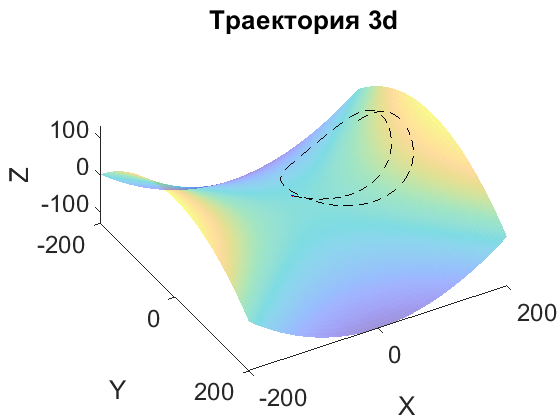

fs = 18;

figure
hold on
title('Траектория 3d')
[X,Y] = meshgrid(-200:5:200);  
xlabel('X')
ylabel('Y')
zlabel('Z')
Z = surf_fcn(X,Y);
surf(X,Y,Z, 'FaceAlpha',0.5, 'EdgeColor', 'None')
plot_frame(initial_r, initial_q)
plot3(act_states(1,:),act_states(2,:),act_states(3,:), 'k--');
set(gca,'FontSize',fs)
view(30,-60)

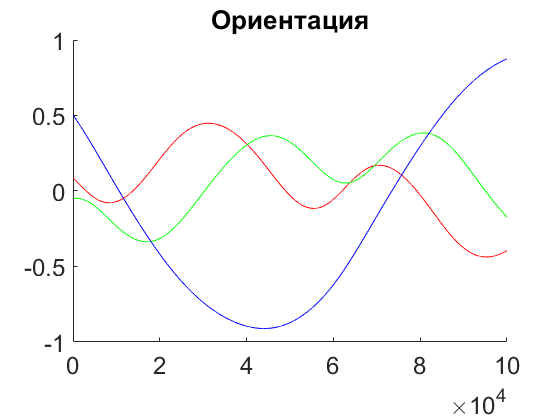


% figure
% hold on
% title('Траектория 2d')
% % plot(x_est, y_est, 'k')
% plot(x_act, y_act, 'k--')
% set(gca,'FontSize',fs)

figure
hold on
title('Ориентация')
plot(qx_est, 'r')
plot(qx_act, 'r--')
plot(qy_est, 'g')
plot(qy_act, 'g--')
plot(qz_est, 'b')
plot(qz_act, 'b--')
set(gca,'FontSize',fs)

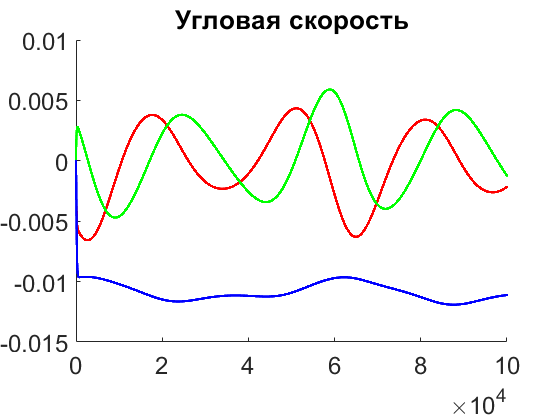


figure
hold on
title('Угловая скорость')
plot(wx_act, 'r--')
plot(wy_act, 'g--')
plot(wz_act, 'b--')
plot(wx_mes, 'r.')
plot(wy_mes, 'g.')
plot(wz_mes, 'b.')
set(gca,'FontSize',fs)

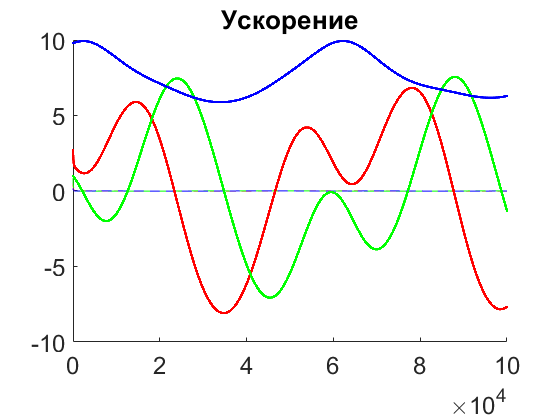


figure
hold on
title('Ускорение')
plot(ax_act, 'r--')
plot(ay_act, 'g--')
plot(az_act, 'b--')
plot(ax_mes, 'r.')
plot(ay_mes, 'g.')
plot(az_mes, 'b.')
set(gca,'FontSize',fs)

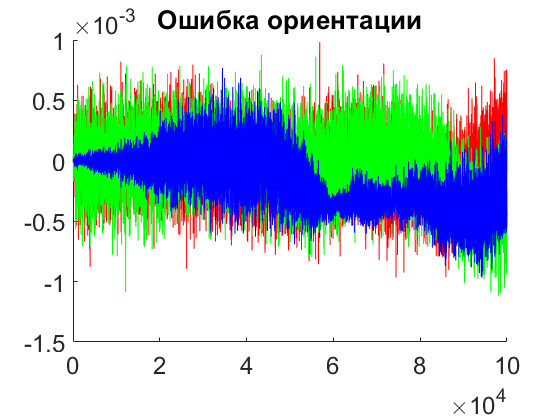


figure
hold on
title('Ошибка ориентации')
plot(qx_est-qx_act, 'r')
plot(qy_est-qy_act, 'g')
plot(qz_est-qz_act, 'b')
set(gca,'FontSize',fs)

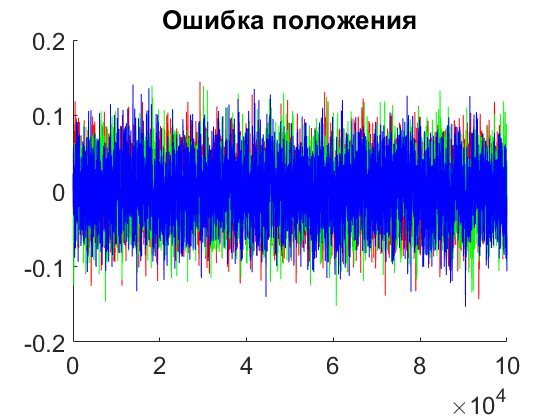


figure
hold on
title('Ошибка положения')
plot(x_est-x_act, 'r')
plot(y_est-y_act, 'g')
plot(z_est-z_act, 'b')
set(gca,'FontSize',fs)

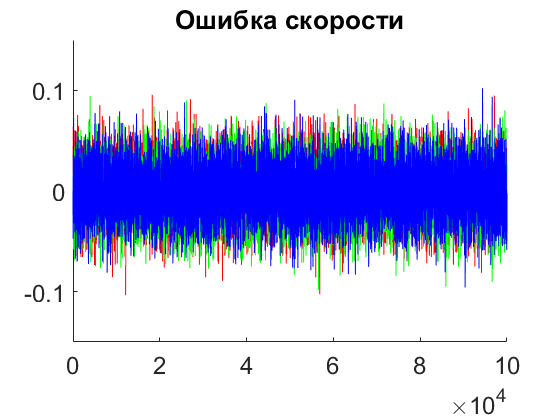


figure
hold on
title('Ошибка скорости')
plot(vx_est-vx_act, 'r')
plot(vy_est-vy_act, 'g')
plot(vz_est-vz_act, 'b')
set(gca,'FontSize',fs)

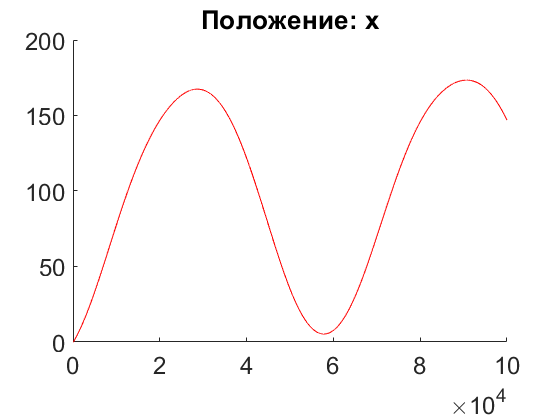


% plot_legend(1) = 'q^w_{est}';
% plot_legend(2).str = 'qw_act';
% plot_legend(3).str = 'q^x_{est}';
% plot_legend(4).str = 'qx_act';
% plot_legend(5).str = 'q^y_{est}';
% plot_legend(6).str = 'qy_act';
% plot_legend(7).str = 'q^z_{est}';
% plot_legend(8).str = 'qz_act';
% lgd = legend(plot_legend);
% lgd.FontSize = fs;

figure
hold on
title('Положение: x')
plot(x_est, 'r')
plot(x_act, 'r--')
set(gca,'FontSize',fs)

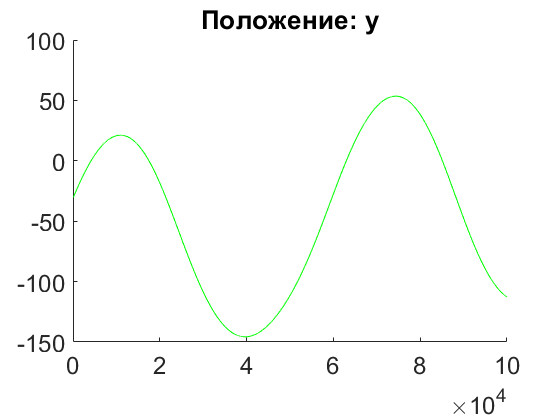


figure
hold on
title('Положение: y')
plot(y_est, 'g')
plot(y_act, 'g--')
set(gca,'FontSize',fs)

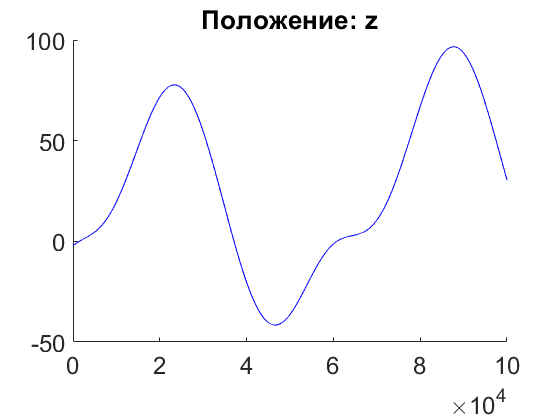


figure
hold on
title('Положение: z')
plot(z_est, 'b')
plot(z_act, 'b--')
set(gca,'FontSize',fs)

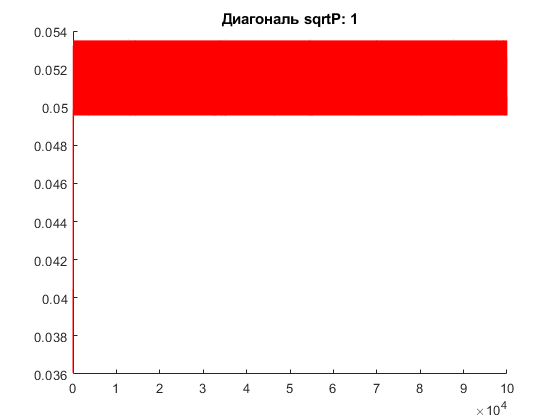

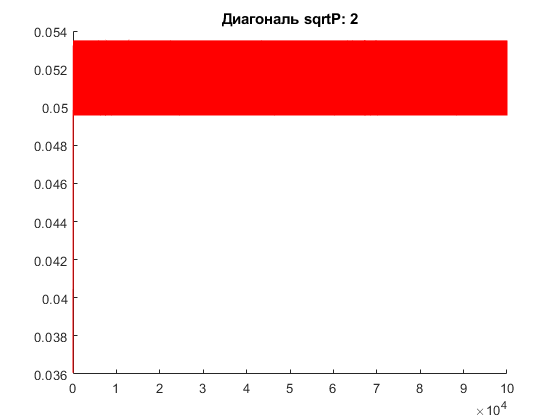

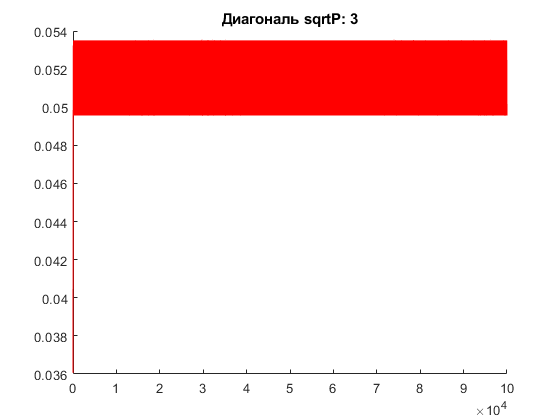

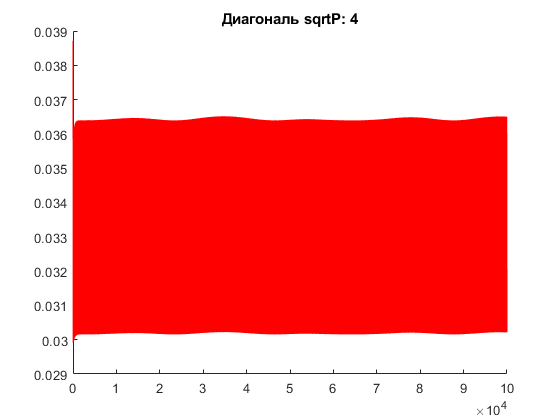

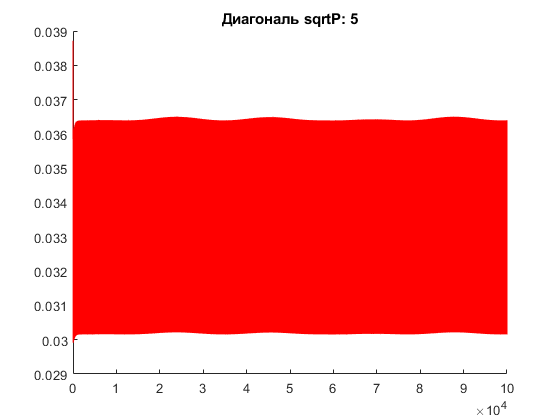

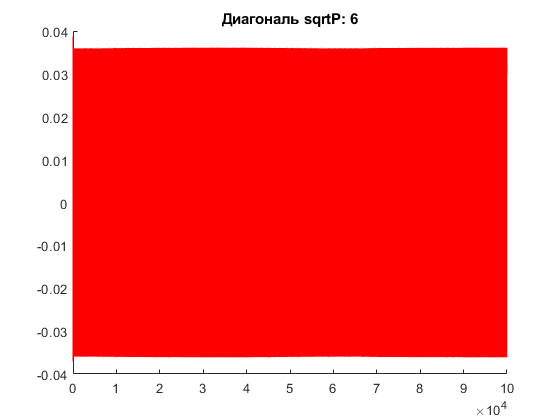

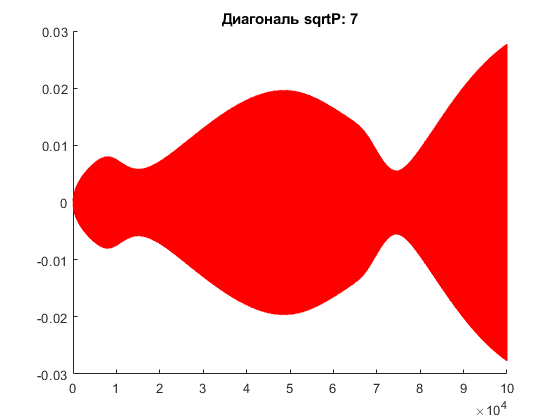

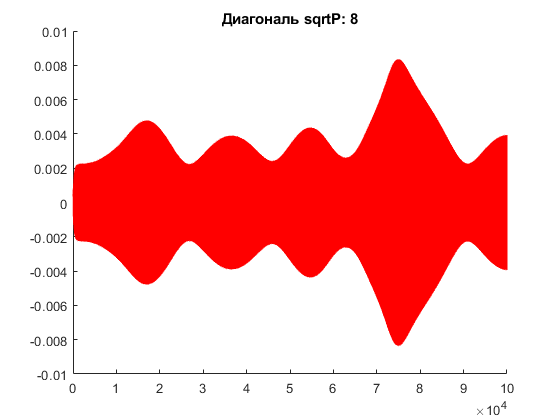


sizeP = size(sqrtP_diag(:, 1));
for i = 1:sizeP(1)
    figure
    hold on
    title(['Диагональ sqrtP: ' num2str(i)])
    plot(sqrtP_diag(i, :), 'r')
end

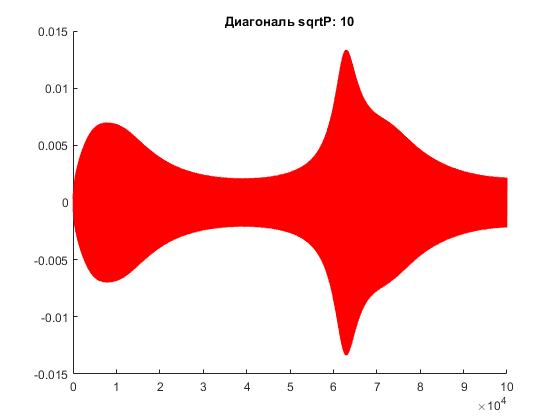

set(gca,'FontSize',floor(fs/2))



% sizeR = size(sqrtR_diag(:, 1));
% for i = 1:sizeR(1)
%     figure
%     hold on
%     title(['Диагональ sqrtR: ' num2str(i)])
%     plot(sqrtR_diag(i, :), 'r')
% end
% set(gca,'FontSize',floor(fs/2))

